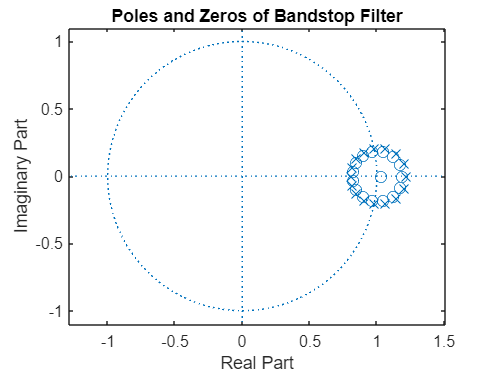

%parameters needed for stopband butter function
Omega_stopband_start = 5*pi/24;
Omega_stopband_end = 11*pi/24;
Fs = 1000; % Sampling frequency (not specified in problem)
v = [Omega_stopband_start/(Fs/2), Omega_stopband_end/(Fs/2)];

% Eighth-order digital bandstop filter
[b_bandstop, a_bandstop] = butter(8, v, 'stop');
figure;
zplane(b_bandstop, a_bandstop);
title('Poles and Zeros of Bandstop Filter');

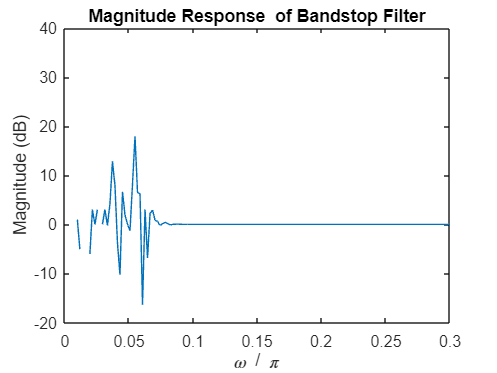

[h,w] = freqz(b_bandstop,a_bandstop);
dB = mag2db(abs(h)); %dB = 20 log10(|h|).
plot(w/pi,dB)
xlabel('\omega / \pi')
xlim([0, .3]);
ylabel('Magnitude (dB)')
title('Magnitude Response  of Bandstop Filter');